# PID Controller Design and Analysis

                                                                                               Tejavath Srinivas_241098

## Assignment 2

## Problem 1: Basic Plant Response Analysis

clc; clear; close all;
s = tf('s');
G = 100/(s^2 + 15*s + 50);

a) Open Loop

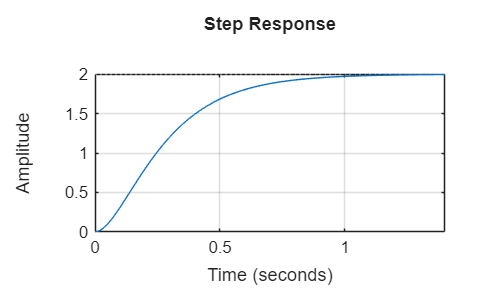

figure; step(G); grid on;

info_ol = stepinfo(G);
ess_ol = abs(1 - dcgain(G));

b) P Controller (Kp = 0.5)

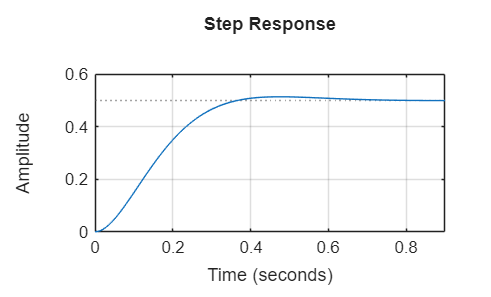

Kp = 0.5;
Gp = feedback(Kp*G,1);

figure; step(Gp); grid on;

info_p = stepinfo(Gp);
ess_p = abs(1 - dcgain(Gp));

c) PI Controller (Kp = 0.5, Ki = 1.5)

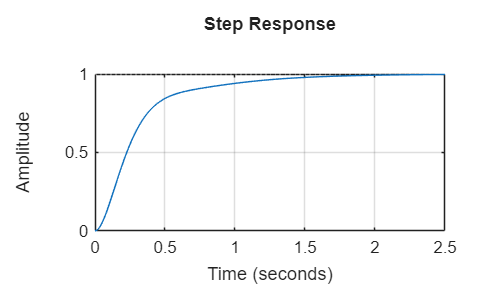

Ki = 1.5;
Gpi = feedback(pid(Kp,Ki)*G,1);

figure; step(Gpi); grid on;

info_pi = stepinfo(Gpi);

d)PID Controller (Tuned)

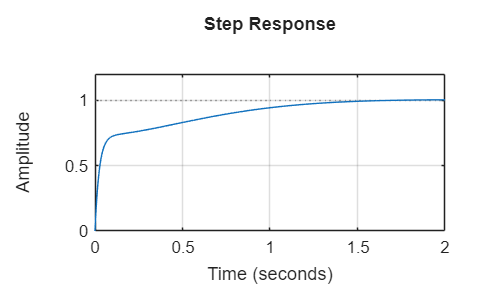

Gpid = feedback(pid(1.2,2.5,0.3)*G,1);

figure; step(Gpid); grid on;

info_pid = stepinfo(Gpid);

## Problem 2: Complex Input Tracking

t = 0:0.01:20;

(a) Multi-Step Input

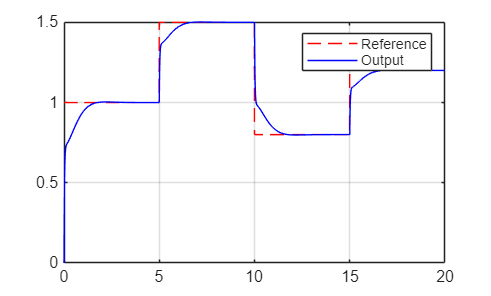

r = ones(size(t));
r(t>=5)=1.5; r(t>=10)=0.8; r(t>=15)=1.2;

y = lsim(Gpid,r,t);

figure;
plot(t,r,'r--',t,y,'b'); grid on;
legend('Reference','Output');

(b) Ramp Input

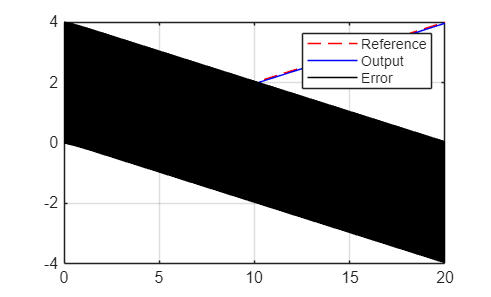

r = 0.2*t;
y = lsim(Gpid,r,t);

figure;
plot(t,r,'r--',t,y,'b',t,r-y,'k'); grid on;
legend('Reference','Output','Error');

(c) Sinusoidal Input

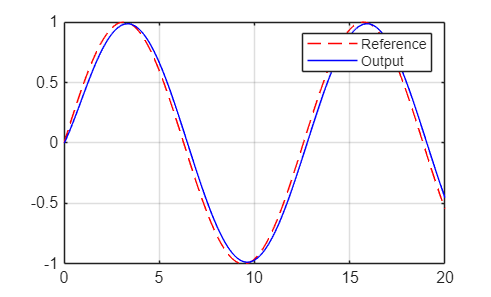

r = sin(0.5*t);
y = lsim(Gpid,r,t);

figure;
plot(t,r,'r--',t,y,'b'); grid on;
legend('Reference','Output');

## Problem 3: Practical PID Implementation

Plant

G2 = 50/(s^3 + 8*s^2 + 25*s + 20);

(a) PI without Anti-Windup

Kp=5; Ki=8; dt=0.01;
t=0:dt:20; r=5*ones(size(t));
y=zeros(size(t)); u=zeros(size(t)); eint=0; ulim=10;

for i=2:length(t)
    e = r(i)-y(i-1);
    eint = eint + e*dt;
    u(i) = max(min(Kp*e + Ki*eint, ulim), -ulim);
    yt = lsim(G2,u(1:i),t(1:i));
    y(i) = yt(end);
end

(b) PI with Anti-Windup

y_aw=zeros(size(t)); u=zeros(size(t)); eint=0; Kt=sqrt(Ki);

for i=2:length(t)
    e = r(i)-y_aw(i-1);
    u0 = Kp*e + Ki*eint;
    u(i) = max(min(u0,ulim),-ulim);
    eint = eint + (e + (u(i)-u0)/Kt)*dt;
    yt = lsim(G2,u(1:i),t(1:i));
    y_aw(i) = yt(end);
end

(c) Derivative Noise (Short)

noise = 0.05*randn(size(y_aw));
y_noisy = y_aw + noise;

(d) Complex Trajectory

r=zeros(size(t));
for i=1:length(t)
    if t(i)<2, r(i)=0.5*t(i);
    elseif t(i)<4, r(i)=1;
    elseif t(i)<8, r(i)=1+0.5*sin(2*pi*(t(i)-4));
    elseif t(i)<10, r(i)=2;
    elseif t(i)<15, r(i)=2-0.3*(t(i)-10);
    else, r(i)=0.5; end
end
eRMS = sqrt(mean((r-y_aw).^2));